## **Consider the following constrained NLP:**


$$\min x_1^2 - 6x_1 + x_2^3 - 3x_2 \\

\text{s.t.} \\

x_1^2 + x_2^2 - 4 = 0.$$


close all

ObjConstant =100000

ObjConstant = 100000


ConstrMultiplier = 60

ConstrMultiplier = 60

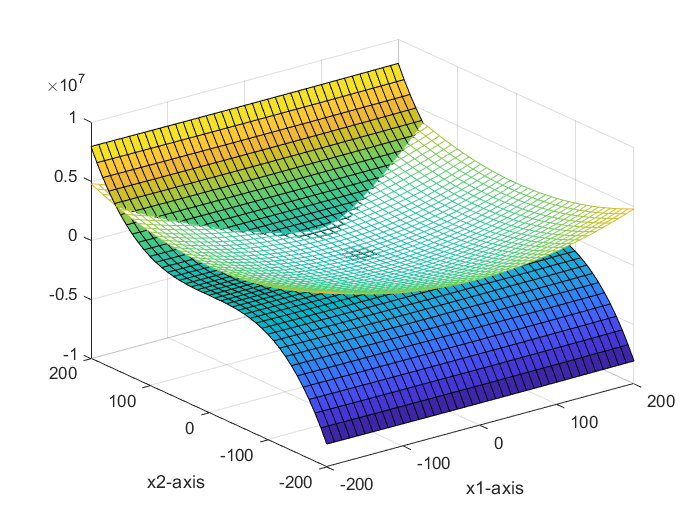


[x1,x2] = meshgrid(-200:10:200,-200:10:200);

objFunc = power(x1, 2) - 6 * x1 + power(x2, 3) - 3 * x2 - ObjConstant;

cons1 = power(x1, 2) + power(x2, 2) - 4;

surf(x1, x2, objFunc);

xlabel('x1-axis')
ylabel('x2-axis')

hold on
mesh(x1, x2, ConstrMultiplier * cons1);


%hold off

## **Consider the following constrained NLP:**


$$\min x_1^2 + x_2^2 \\

\text{s.t.} \\

x_1 - x_2 - 3 = 0.$$


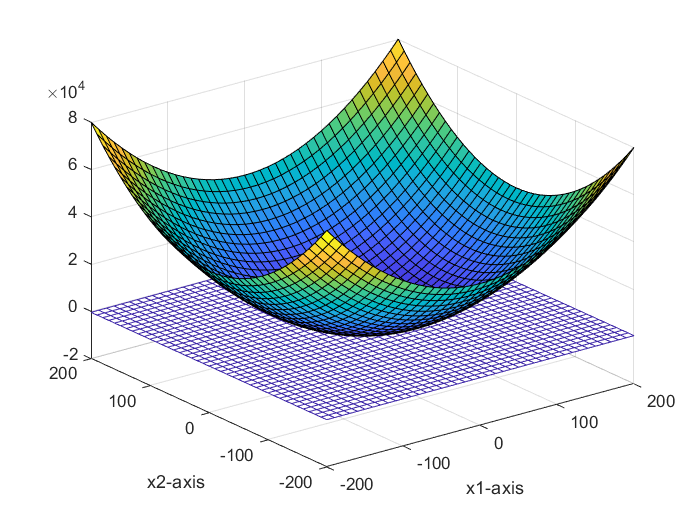

close all

[x1,x2] = meshgrid(-200:10:200,-200:10:200);

objFunc = power(x1, 2) + power(x2, 2);

cons1 = x1 - x2 - 3;

surf(x1, x2, objFunc);

xlabel('x1-axis')
ylabel('x2-axis')

hold on
mesh(x1, x2, cons1);

plot(1.5, -1.5,'o r', 'MarkerFaceColor', 'm')

## Constrained Nonlinear Optimization Problem 

### Solve with MATLAB Optimization Toolbox

Minimize the objective function


$$f(x,y)=e^x\left (4x^2 + 2y^2 + 4xy + 2y -1\right ).$$


with respect to the constraints


$$\frac{xy}{2}+(x+2)^2 + \frac{(y-2)^2}{2} \le 2.$$



$$x + 2 e^{((y-a) / 4)} \leq 0$$



$$-10 \leq x \leq 10$$



$$-10 \leq y$$


% https://www.mathworks.com/products/optimization.html

% https://www.mathworks.com/help/optim/ug/solve-constrained-nonlinear-optimization-problem-based.html

% openExample('optim/SolveConstrainedNonlinearOptimizationProblemBasedExample')

**Define the objective function **

close all

prob = optimproblem

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.



x = optimvar('x', 'LowerBound', -10, 'UpperBound', 10)

x =   OptimizationVariable with properties:

          Name: 'x'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -10
    UpperBound: 10

  See variables with showvar.
  See bounds with showbounds.


y = optimvar('y', 'LowerBound', -10)

y =   OptimizationVariable with properties:

          Name: 'y'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -10
    UpperBound: Inf

  See variables with showvar.
  See bounds with showbounds.



obj = fcn2optimexpr(@objfun,x,y);

prob.Objective = obj

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with showproblem.


**Add the first constraint **

TiltEllipse = x.*y/2 + (x+2).^2 + (y-2).^2/2 <= 2

TiltEllipse =   Quadratic OptimizationConstraint

    ((((x .* y) ./ 2) + (x + 2).^2) + ((y - 2).^2 ./ 2)) <= 2



prob.Constraints.constr = TiltEllipse

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with showproblem.


**Add the second constraint **

a = 4;

expr = fcn2optimexpr(@constraint2, x, y, a)

expr =   Nonlinear OptimizationExpression

    constraint2(x, y, 4)



secondConstr = expr <= 0;

prob.Constraints.exponentialConstr = secondConstr

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 2 OptimizationConstraints

  See problem formulation with showproblem.



showproblem(prob)


  OptimizationProblem : 

	minimize :
       objfun(x, y)

	subject to constr:
       ((((x .* y) ./ 2) + (x + 2).^2) + ((y - 2).^2 ./ 2)) <= 2

	subject to exponentialConstr:
       constraint2(x, y, 4) <= 0

	variable bounds:
       -10 <= x <= 10

       -10 <= y



**Set an intial point**

x0.x = -3;
x0.y = 3;

**Solve the problem **

[sol,fval, exitflag] = solve(prob,x0)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<<a href = "matlab: createExitMsg({'optimlib:sqpLineSearch:Exit1basic'},{'optimlib:sqpLineSearch:Exit1detailed','4.009179e-07','1.000000e-06','0.000000e+00','1.000000e-06'},true,true);;">stopping criteria details</a

sol = struct with fields:
    x: -5.2813
    y: 4.6814


fval = 0.3299

exitflag =     OptimalSolution


**Try another starting point **

x0.x = -1;
x0.y = 1;

[sol2,fval2, exitflag2, output] = solve(prob,x0)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<<a href = "matlab: createExitMsg({'optimlib:sqpLineSearch:Exit1basic'},{'optimlib:sqpLineSearch:Exit1detailed','3.649462e-07','1.000000e-06','0.000000e+00','1.000000e-06'},true,true);;">stopping criteria details</a

sol2 = struct with fields:
    x: -0.8580
    y: 0.6147


fval2 = 0.7717

exitflag2 =     OptimalSolution


output = struct with fields:
         iterations: 13
          funcCount: 42
    constrviolation: 0
           stepsize: 4.0050e-10
          algorithm: 'interior-point'
      firstorderopt: 4.0000e-07
       cgiterations: 0
            message: '↵Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 3.649462e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵'
             solver: 'fmincon'


**Visualize the solution **

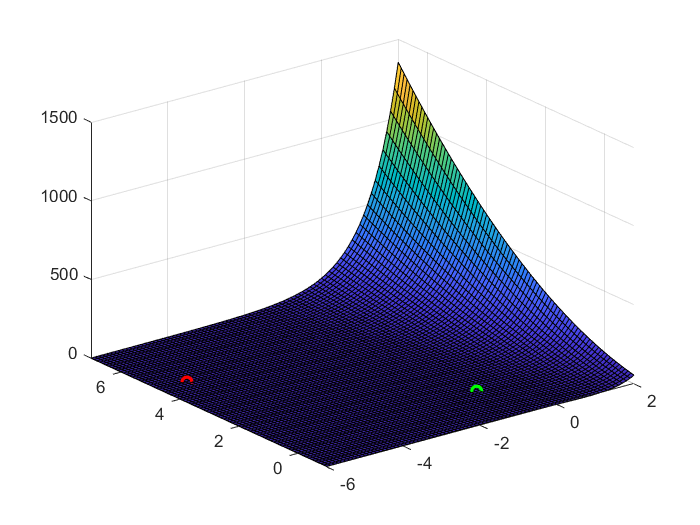

[x, y] = meshgrid(-6:0.1:2,-1:0.1:7);

objFunc = objfun(x, y);

g1 = @(x,y) x.*y/2+(x+2).^2+(y-2).^2/2-2;

g2 = @(x,y) x + 2 * exp((y-a) / 4);

surf(x, y, objFunc);

hold on 
plot(sol.x,sol.y,'ro','LineWidth',2)
plot(sol2.x,sol2.y,'go','LineWidth',2)
hold off 

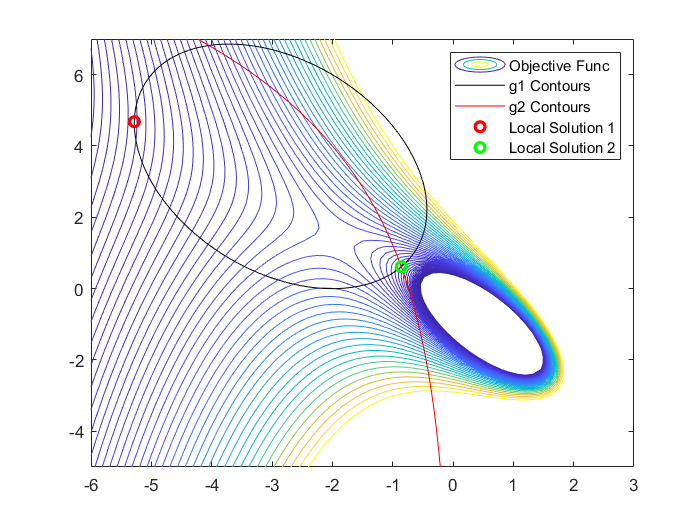


rnge = [-6 3 -5 7];
fcontour(@objfun,'LevelList',logspace(-1,1))
axis(rnge);

hold on 
fimplicit(g1,'k-')
fimplicit(g2,'r-')
plot(sol.x,sol.y,'ro','LineWidth',2)
plot(sol2.x,sol2.y,'go','LineWidth',2)
legend('Objective Func','g1 Contours', 'g2 Contours','Local Solution 1','Local Solution 2','Location','northeast');
hold off 

**Check which constraints are active and inactive at the local optimums **

constraint1(sol.x, sol.y)

ans = -8.0503e-06

constraint2(sol.x, sol.y, 4)

ans = -2.9098


constraint1(sol2.x, sol2.y)

ans = -1.4139e-06

constraint2(sol2.x, sol2.y, 4)

ans = -1.1022e-06

function f = objfun(x,y)
    f = exp(x) .* (4 * x.^2 + 2 * y.^2 + 4 * x .* y + 2 * y - 1);
end

function constr = constraint1(x, y)
    constr = x.*y/2+(x+2).^2+(y-2).^2/2-2;
end

function constr = constraint2(x, y, a)
    constr = x + 2 * exp((y-a) / 4);
end